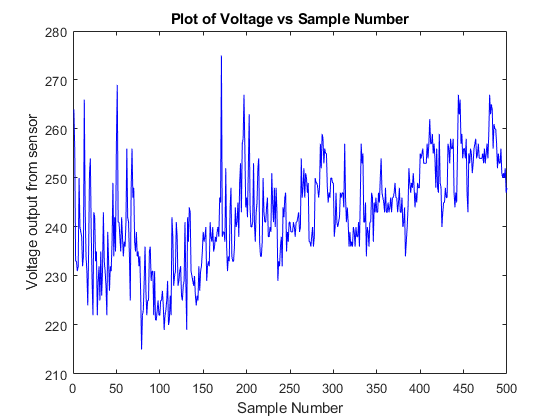

nat_finger_1 = csvread('D:\nf_finger_1_moving.txt');
%nat_finger_2 = csvread('D:\ej_finger_4.txt');
%nat_finger_3 = csvread('C:\Users\natal\OneDrive - Heriot-Watt University\Semester 2\embedded\nat_finger_3.txt');


data = nat_finger_1;

%data2 = nat_finger_2;
[x, y] = size(data);
x_values = [1:1:x]; 

figure;
plot(x_values(1, :), data, 'b');
title('Plot of Voltage vs Sample Number')
xlabel('Sample Number')
ylabel('Voltage output from sensor')
% figure%  plot(x_values(1, :), data2, 'r');
%  title('finger voltage')

alpha = 0.9;

%%initial conditions for filter
output(1) = 0;
temp(1) = data(2) + alpha * data(1);

for i = 2:(x-1)
        %output(i) = data(1); %alpha*data(1);
        %output2(i) = 0; %alpha*data2(1);
      
       temp(i) = data(i) + alpha * data(i-1);
       output(i) = temp(i) - temp(i-1);
%        
    %temp2(i) = data2(i) + alpha * data2(i-1);
      %output2(i+1) = temp2(i+1) - temp2(i);
%        temp2(i) = data2(i) + alpha * data2(i-1);
%        output2(i) = temp2(i) - temp(i-1);

end

output(1) = median(output);
output(2) = median(output);

x_values2 = [1:1:499];
hold on

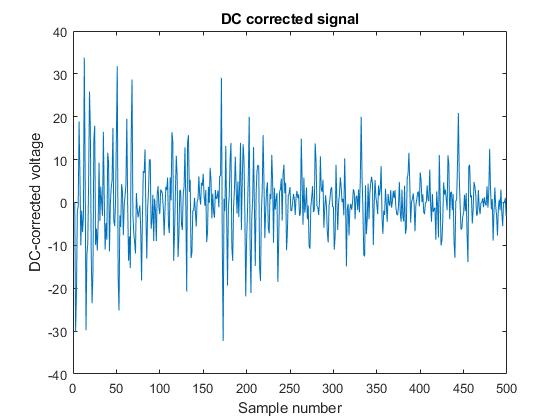

figure,
plot(x_values2(1, :), output);
title('DC corrected signal')
xlabel('Sample number')
ylabel('DC-corrected voltage')

% plot(x_values(1, :), output2);
% title('DC corrected data 2')


%mean_data1 = mean(data);
%mean_data2 = mean(data2);

N_pos = sum(output(:) >= 0); %Number values above and below average
N_neg = sum(output(:) <= 0);
[n m] = size(output);

D_pos = sum(N_pos);
m_o = mean(output); %average signal value
filtered_signal = m_o - (N_pos - N_neg) * D_pos/(n^2); 

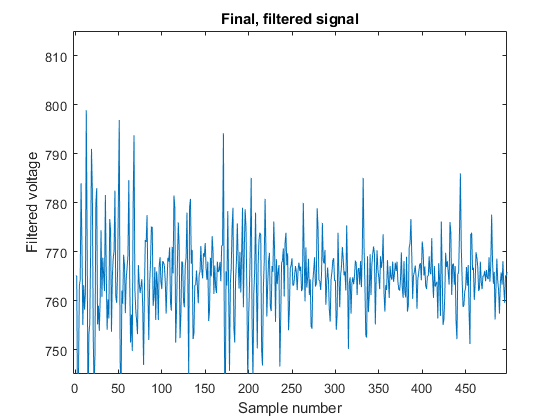

filt_sig = output - filtered_signal;
figure,
plot(x_values2(1, :), filt_sig);
title('Final, filtered signal')
xlabel('Sample number')
ylabel('Filtered voltage')

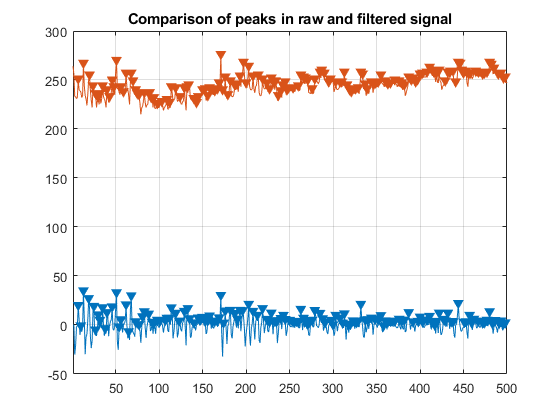

% plot(x_values(1, :), filt_sig);
% title('data2 filtered')

findpeaks(output);
hold on
findpeaks(data);
title('Comparison of peaks in raw and filtered signal')

point = findpeaks(data);
bpm = findpeaks(filt_sig)

bpm =   783.9397  763.1397  798.8397  790.9397  782.9397  758.9397  774.3397  768.7397  781.5397  760.2397  776.6397  782.4397  796.8397  762.0397  769.3397  784.5397  757.1397  793.7397  767.2397  764.3397  772.3397  777.4397  775.0397  766.8397  765.9397  768.8397  768.0397  768.7397  770.8397  770.9397  781.4397  775.9397  767.9397  777.9397  780.7397  770.3397  766.1397  771.1397  769.6397  771.7397  767.9397  768.7397  773.1397  767.1397  767.9397  767.8397  771.2397  794.1397  765.9397  778.2397


medFilt = dsp.MedianFilter

medFilt =   dsp.MedianFilter with properties:

    WindowLength: 5


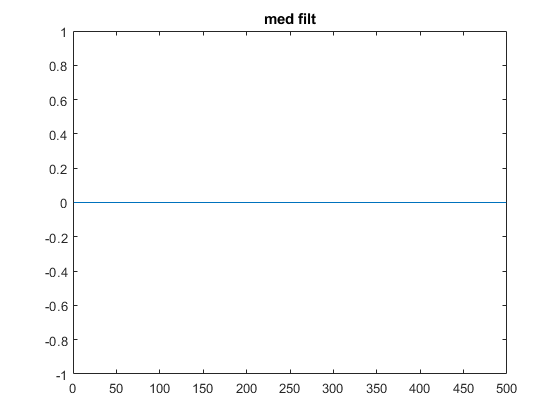

 
y = medFilt(output);
figure,
plot(x_values2(1, :), y);
title('med filt')


findpeaks(y);


medFilt = dsp.MedianFilter('WindowLength', 3);
y = medFilt(filt_sig);
 figure,
plot(x_values2(1, :), y);
title('Median Filtered signal')

xlabel('Sample number')
ylabel('Filtered voltage')




bpm = findpeaks(filt_sig)


movAvg = dsp.MovingAverage

movAvg =   dsp.MovingAverage with properties:

                 Method: 'Sliding window'
    SpecifyWindowLength: true
           WindowLength: 4


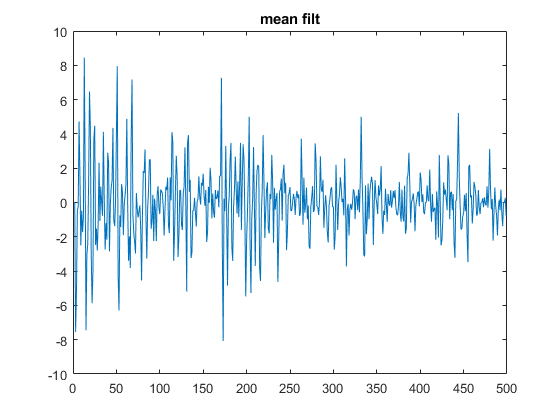

z = movAvg(data);
figure,
plot(x_values(1, :), z);
title('Moving Average Filtered Signal')

xlabel('Sample number')
ylabel('Filtered voltage')


movMax = dsp.MovingMaximum

movMax =   dsp.MovingMaximum with properties:

    SpecifyWindowLength: true
           WindowLength: 4


q = movMax(output);
bpm_z = findpeaks(z);
findpeaks(z);